# Shadow Bot Calculations

**The governing equations are : **

Let the Thrust supplied by the EDF be T,

and the Weight off the bot be W, then

for **No Sliding**,


$$\mathit{\mathbf{T}}\ge \frac{\mathit{\mathbf{W}}}{\mu }$$


and for **No Toppling**,


$$\mathit{\mathbf{W}}\le \mathit{\mathbf{T}}∗\frac{\mathit{\mathbf{x}}}{\mathit{\mathbf{c}}}$$


where,

x is the point of application of thrust from the rear wheel of the bot,

c is the clearance of the bot with the ground.

For the bot to move ,

Motor torque,**M** required is ,


$$\mathit{\mathbf{M}}\ge \frac{\mathit{\mathbf{W}}∗\mathit{\mathbf{R}}}{2}$$


where,

R = radius of the wheel.

And also the bot should satisfy these conditions while running,


$$\mathit{\mathbf{T}}\ge \mathit{\mathbf{W}}∗\frac{\mathit{\mathbf{c}}}{\mathit{\mathbf{x}}}-\frac{\mathit{\mathbf{M}}}{\mathit{\mathbf{x}}}$$



$$\mathit{\mathbf{M}}\ge \text{ }\frac{\left(\mu \frac{\mathit{\mathbf{T}}}{2}-\frac{\mu \mathit{\mathbf{W}}}{4}+{\mathit{\mathbf{m}}}_0 \frac{\mathit{\mathbf{W}}}{\left(\frac{\mathit{\mathbf{W}}}{\mathit{\mathbf{g}}}+2{\mathit{\mathbf{m}}}_0 \right)}\right)}{\left(\frac{{\mathit{\mathbf{m}}}_0 }{\left(\mathit{\mathbf{R}}{\mathit{\mathbf{m}}}_0 +\frac{\mathit{\mathbf{W}}}{\mathit{\mathbf{g}}}\right)}-\frac{\mu }{2\mathit{\mathbf{L}}}\right)}$$


which has to ensured.

**Thrust vs W_max of the bot calculation for different Thrust_distance(x)/clearance of bot ratios keeping other parameters fixed :**

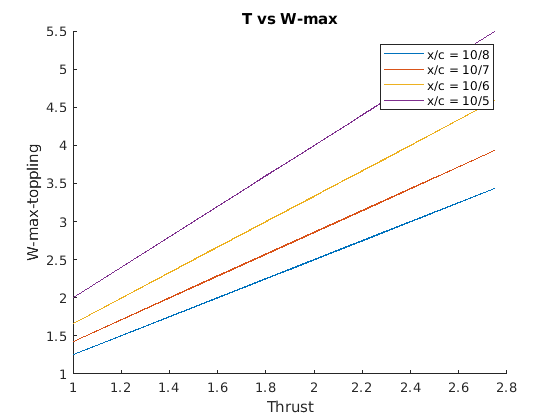

% Thrust vs W_max of the bot calculation for different
% Thrust_distance(x)/clearance of bot ratios keeping 
% other parameters fixed
x = table2array(TvsM(13:27,2));
y = table2array(TvsM(13:27,10));
x1 = table2array(TvsM(28:42,2));
y1 = table2array(TvsM(28:42,10));
x2 = table2array(TvsM(43:57,2));
y2 = table2array(TvsM(43:57,10));
x3 = table2array(TvsM(58:72,2));
y3 = table2array(TvsM(58:72,10));
figure;
hold on;
xlabel('Thrust');
ylabel('W-max-toppling');
title('T vs W-max');
plot(x,y,x1,y1,x2,y2,x3,y3);
legend('x/c = 10/8','x/c = 10/7','x/c = 10/6','x/c = 10/5');
hold off;

**Motor Torque vs Thrust for the same above conditions :**

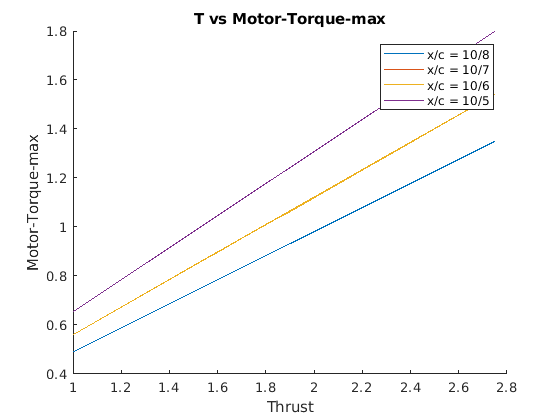

% Motor Torque vs Thrust for the same above conditions 
z = table2array(TvsM(13:27,12));
z1 = table2array(TvsM(28:42,12));
z3 = table2array(TvsM(43:57,12));
z4 = table2array(TvsM(58:72,12));
figure;
hold on;
xlabel('Thrust');
ylabel('Motor-Torque-max');
title('T vs Motor-Torque-max');
plot(x,z,x1,z1,x2,z2,x3,z3);
legend('x/c = 10/8','x/c = 10/7','x/c = 10/6','x/c = 10/5');
hold off;

**The Min Motor Torque** ,${\mathit{\mathbf{M}}}_{\mathbf{min}}$ $\ge \frac{{\mathit{\mathbf{W}}}_{\mathbf{min}} ∗\mathit{\mathbf{R}}}{2}$

**and **$W_{\min }$** = **$\mu ∗\mathit{\mathbf{T}}$** and hence depends on **$\mu$** and T only. It does not depend on other parameters.**

***To play around with the input values use of this section : ***

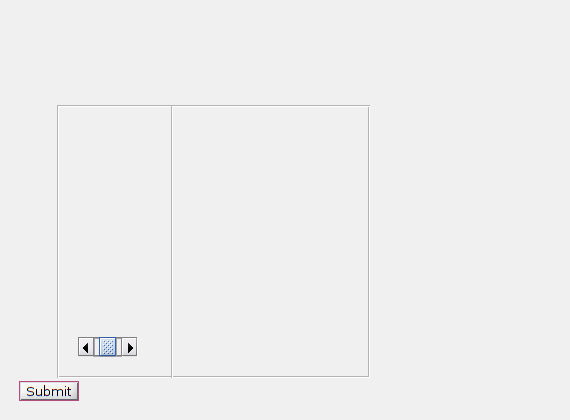

%{
% To Play around with the input values use this section]
Thrust = 0;
f = figure;
p = uipanel(f,'Position',[0.1 0.1 0.35 0.65]);
c = uicontrol(p,'Style','slider');
c.Value = 0.5;
p_ok = uipanel(f,'Position',[0.3 0.1 0.35 0.65]);
ok = uicontrol;
ok.String = 'Submit';

c.Callback = @pushbuttonPlot;
%}






